## Data Preprocess

### Dataset description

The dataset used for this project is the **Street View House Numbers (SVHN)** dataset(http://ufldl.stanford.edu/housenumbers/), which is a real-world image dataset for developing machine learning and object recognition algorithms with minimal requirement on data preprocessing and formatting.

- **SVHN Dataset**: Contains color images of house numbers collected from Google Street View. Each image is 32x32 pixels in RGB format.

- **Contents**: The dataset includes a training set (`train_32x32.mat`) and a test set (`test_32x32.mat`), each containing images (`X`) and their corresponding labels (`y`).

### **Data Preprocessing Steps:**

**            1. Loading the Data**:

**            2. Preparing the Test Dataset**:

**            3. Preparing the Training Dataset**:

**            4. Determining the Size of the Dataset**:

**            5. Setting the Size of the Validation Set**:

**            6. Random Selection for Validation Data**:

**            7. Splitting the Data**:

% load datasets
trainData = load('train_32x32.mat');
testData = load('test_32x32.mat');

% prepare test datasets
X_test = double(testData.X) / 255; 
y_test = categorical(testData.y);

% prepare train datasets
X_full = double(trainData.X) / 255;
y_full = categorical(trainData.y);

% Determine the total size of the dataset
total_samples = size(X_full, 4);

% Set Verification Set Size（20%）
val_size = floor(0.2 * total_samples);

% Randomly select validation data
rng(1); % For repeatability, seed the random number generator
indices = randperm(total_samples);

% Split data to validation datasets and train datasets
X_val = X_full(:,:,:,indices(1:val_size));
y_val = y_full(indices(1:val_size));
X_train = X_full(:,:,:,indices(val_size+1:end));
y_train = y_full(indices(val_size+1:end));

## Create Layer_A

**Layers_A:**

- **Image Input Layer**: Receives a 3-channel image of 32x32 pixels.

- **Convolutional** **Layer**: Use 20 5x5 filters with "same" padding.

- **ReLU** **Layer**: Activation function layer, using ReLU function to increase nonlinearity.

- **Max** **Pooling Layer**: Use a 2x2 window and a stride of 2 to reduce the feature dimension.

- **Fully Connected Layer** : Contains 10 neurons and is used for classification.

- **Softmax Layer**: Converts the output of the fully connected layer into a probability distribution.

- **Classification** **Layer**: Outputs the final classification results.

layers_A = [
    imageInputLayer([32 32 3], 'Name', 'input')
    convolution2dLayer(5, 20, 'Padding', 'same', 'Name', 'conv1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    fullyConnectedLayer(10, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {X_val, y_val}, ...  % 确保使用逗号分隔这一行和下一行
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

## Train net_A

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       10.81% |       2.3052 |       2.3085 |          0.0100 |
|       1 |          30 |       00:00:03 |       21.09% |       19.24% |       2.1983 |       2.2422 |          0.0100 |
|       1 |          50 |       00:00:04 |       19.53% |              |       2.2444 |              |          0.0100 |
|       1 |          60 |       00:00:05 |       16.41% |       18.57% |       2.2415 |   

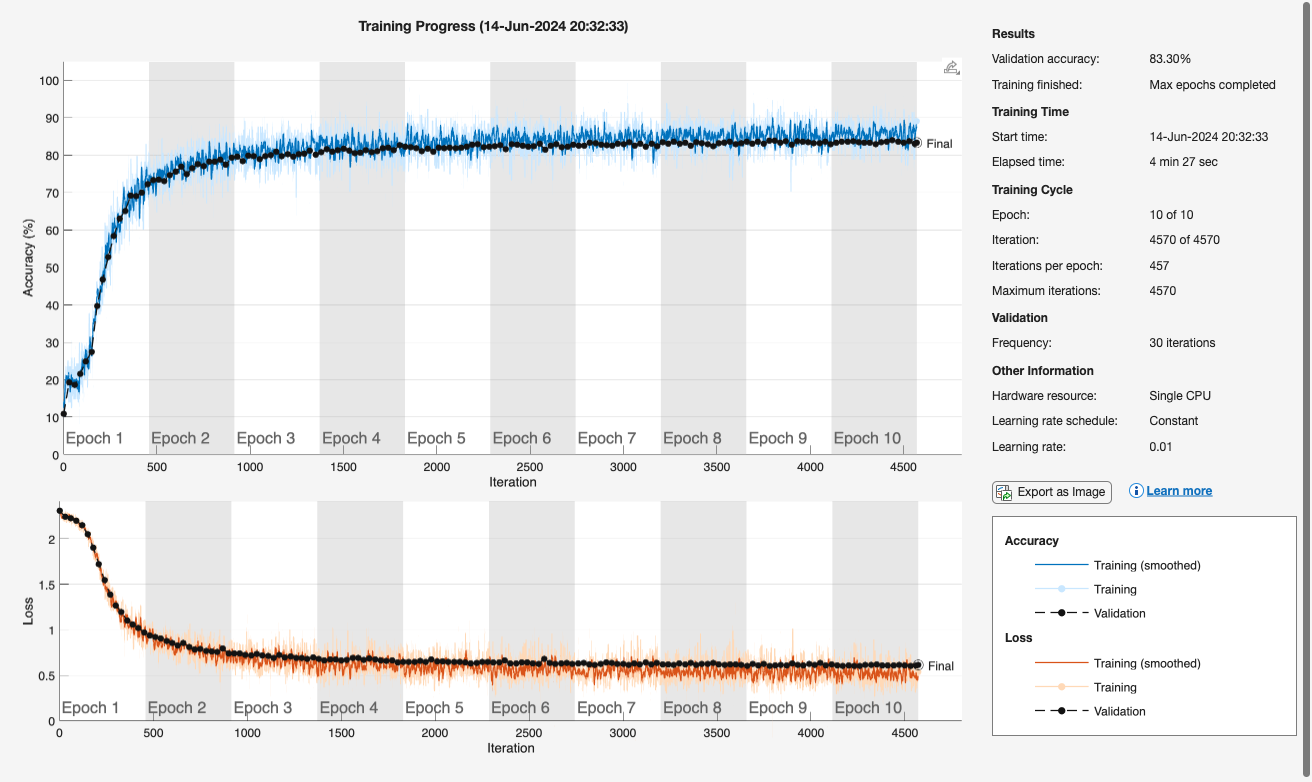

net_A = trainNetwork(X_train, y_train, layers_A, options);

## Evaluate net_A

YPred = classify(net_A, X_test);
accuracy = sum(YPred == y_test) / numel(y_test);
disp(['Test Accuracy for net_A: ', num2str(accuracy)]);

Test Accuracy for net_A: 0.81999


## Create Layer_B

**Layers_B:(Add more convolutional layers and filters)**

- **Image Input Layer**: Same as configuration A.

- **First Convolutional Laye**r: Use 32 5x5 filters with "same" padding.

- **ReLU Layer**: Same as configuration A.

- **Max Pooling Layer** : Same as configuration A.

- **Second Convolutional Layer**: Use 64 5x5 filters with "same" padding.

- **ReLU Laye**r: Same as above.

- **Second Max Pooling Layer** : Same as the first layer.

- **Fully Connected Layer** : Same as configuration A.

- **Softmax Layer**: Same as configuration A.

- **Classification Layer**: Same as configuration A.

layers_B = [
    imageInputLayer([32 32 3], 'Name', 'input')
    convolution2dLayer(5, 32, 'Padding', 'same', 'Name', 'conv1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    convolution2dLayer(5, 64, 'Padding', 'same', 'Name', 'conv2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool2')
    fullyConnectedLayer(10, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];

## Train & Evaluate net_B

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |        2.34% |        8.87% |       2.3103 |       2.3055 |          0.0100 |
|       1 |          30 |       00:00:07 |       14.84% |       18.56% |       2.2528 |       2.2479 |          0.0100 |
|       1 |          50 |       00:00:09 |       21.88% |              |       2.1961 |              |          0.0100 |
|       1 |          60 |       00:00:12 |       18.75% |       18.58% |       2.2135 |   

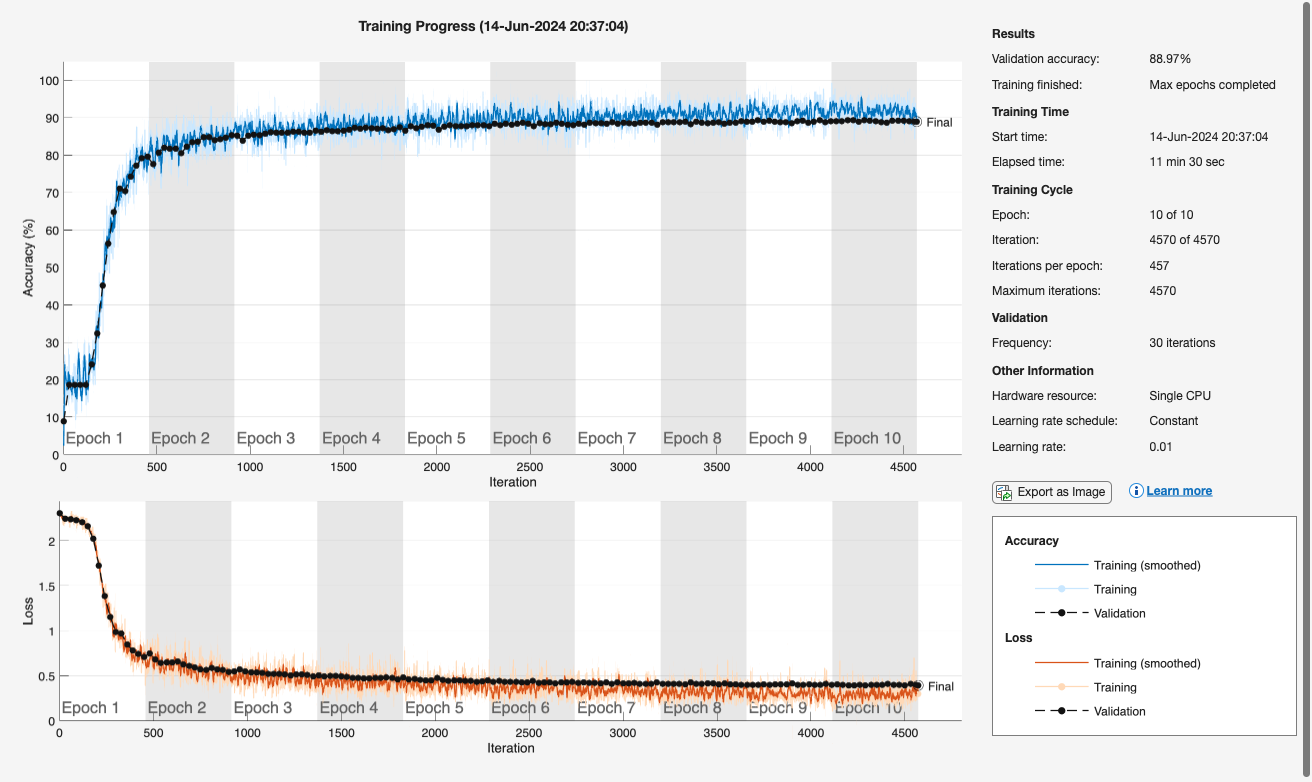

net_B = trainNetwork(X_train, y_train, layers_B, options);


YPred = classify(net_B, X_test);
accuracy = sum(YPred == y_test) / numel(y_test);
disp(['Test Accuracy for net_B: ', num2str(accuracy)]);

Test Accuracy for net_B: 0.87711


## Create Layer_C

**Layers_C:(Add Dropout Layer)**

- **Image Input Laye**r: Same as configuration A.

- **Convolutional Layer**: Use 20 5x5 filters with "same" padding.

- **ReLU Layer**: Same as configuration A.

- **Max Pooling Layer** : Same as configuration A.

- **Dropout Layer**: The dropout rate is 50% to prevent overfitting.

- **Fully Connected Layer** : Same as configuration A.

- **Softmax Layer**: Same as configuration A.

- **Classification Layer**: Same as configuration A.

layers_C = [
    imageInputLayer([32 32 3], 'Name', 'input')
    convolution2dLayer(5, 20, 'Padding', 'same', 'Name', 'conv1')
    reluLayer('Name', 'relu1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    dropoutLayer(0.5, 'Name', 'dropout')
    fullyConnectedLayer(10, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];

## Train & Evaluate net_C

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.03% |        8.19% |       2.3163 |       2.3059 |          0.0100 |
|       1 |          30 |       00:00:03 |       26.56% |       19.58% |       2.2175 |       2.2431 |          0.0100 |
|       1 |          50 |       00:00:04 |       21.09% |              |       2.2368 |              |          0.0100 |
|       1 |          60 |       00:00:05 |       25.00% |       18.67% |       2.1832 |   

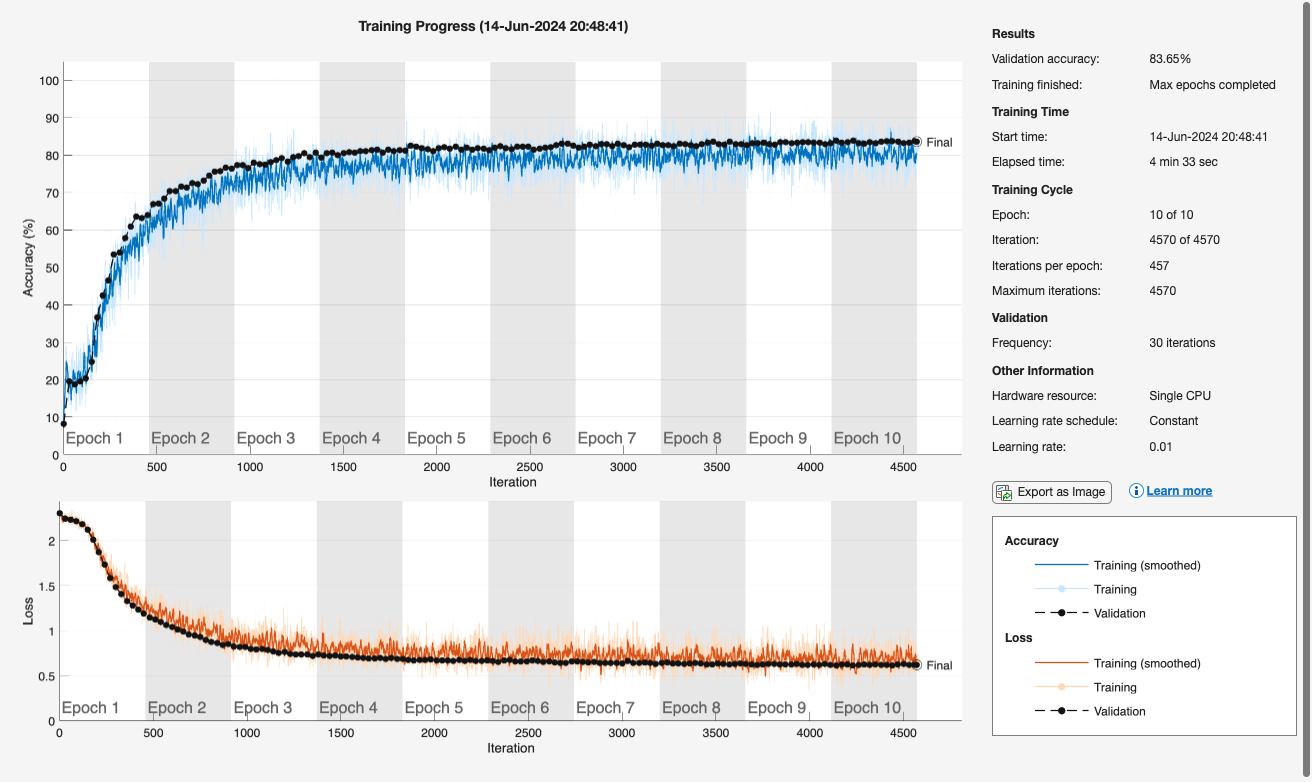

net_C = trainNetwork(X_train, y_train, layers_C, options);


YPred = classify(net_C, X_test);
accuracy = sum(YPred == y_test) / numel(y_test);
disp(['Test Accuracy for net_C: ', num2str(accuracy)]);

Test Accuracy for net_C: 0.82222


## Conclusion

Test Accuracy for net_A: 0.81999 

Test Accuracy for net_B: 0.87711 

Test Accuracy for net_C: 0.82222

**net_A** : Test accuracy is 81.999%. This is a basic network structure with basic convolutional layers, pooling layers, and fully connected layers. This configuration provides a good baseline performance.

**net_B** : The test accuracy is 87.711%. This configuration significantly improves performance by increasing the number of convolutional layers and filters, as well as adding an additional convolutional and pooling layer. More convolutional layers and filters enhance the network's ability to capture complex features, which may be the main reason for its performance improvement.

**net_C**: The test accuracy is 82.222%. This configuration introduces a Dropout layer to reduce overfitting. Although the Dropout layer helps improve the model's generalization ability, in this case, its performance did not significantly exceed the basic configuration A.

## Save the best Net

save('best_network.mat', 'net_B');

## Test the Net

Testing the 'best_network.mat' in function classifyImageScript.m. I input a sample image which is the number '9', and then output the classification of the label.

**Output of the command window:**

Predicted Label: 9